# Module 2 Assessment

## Adjusting a Dark and Rotated Image

Adjusting the brightness of images is one of the most common enhancements. One approach is known as gamma correction. In gamma correction, the value of every pixel in an image is raised to some power, gamma: 𝐼𝑜𝑢𝑡=𝐼𝑖𝑛𝛾�, where 𝐼 is the intensity value of the pixel. 

Depending on the value of 𝛾 the resulting image will be brighter or darker. Before performing gamma correction, the pixel values are rescaled to the range [0 1]. Doing this ensures that the range of values in the resulting output image is also [0 1].

## Project Goal

Your goal is to create a grayscale version of this image that is:

- brightness adjusted using gamma correction with 𝛾=1/2

- straightened by rotating 1 degree while maintaining the image dimensions

- stored as uint8

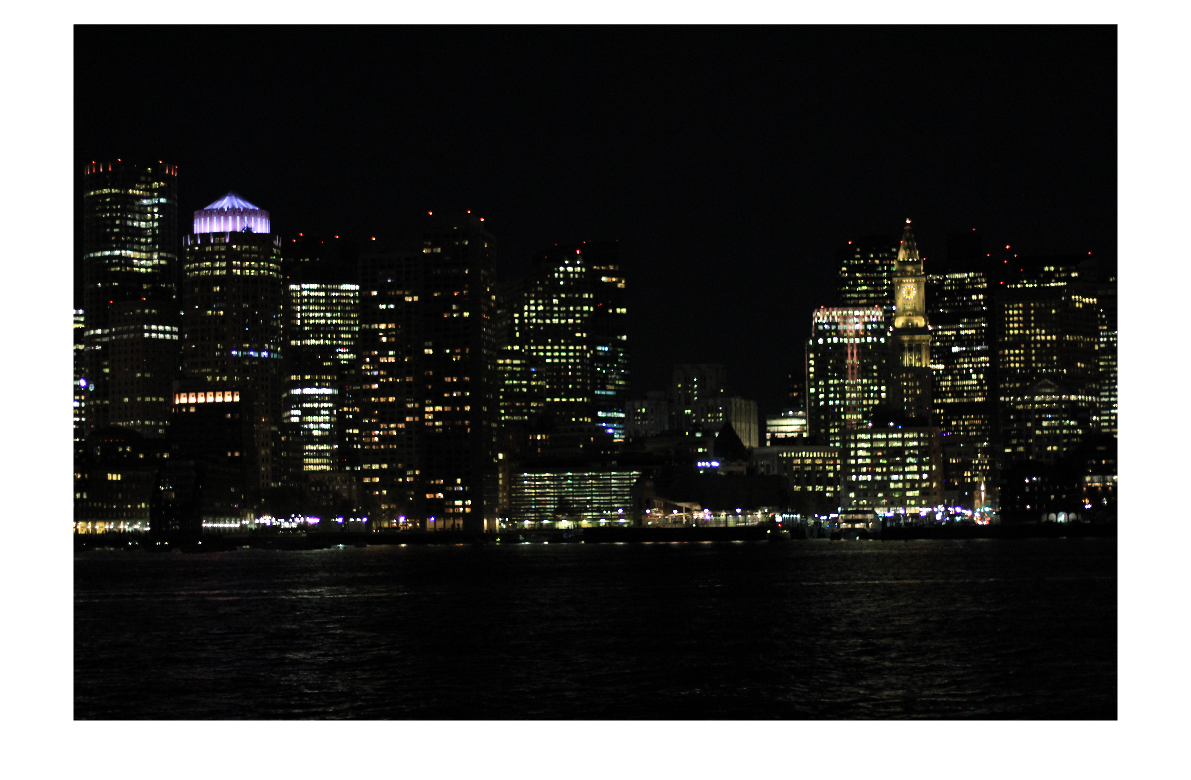

img = imread("boston night.JPG");
imshow(img)

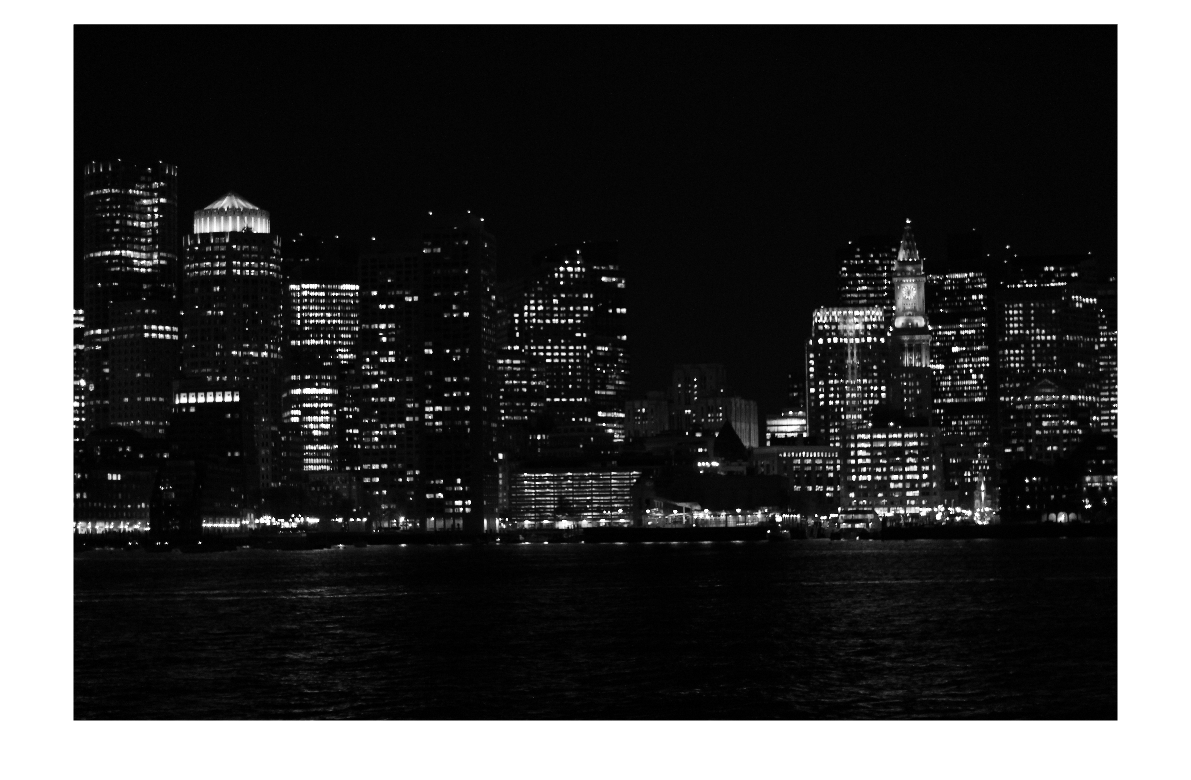

imgGray = im2gray(img);
imshow(imgGray)

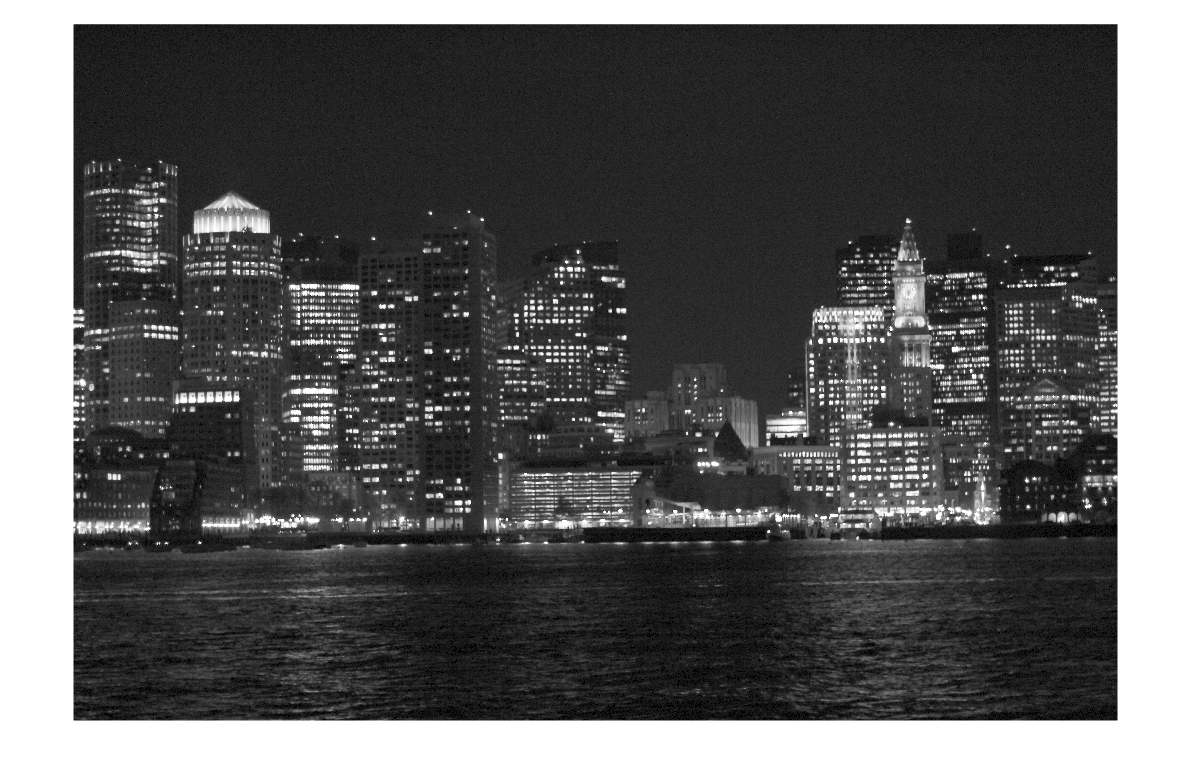

imgGamma = im2double(imgGray).^(0.5);
imshow(imgGamma)

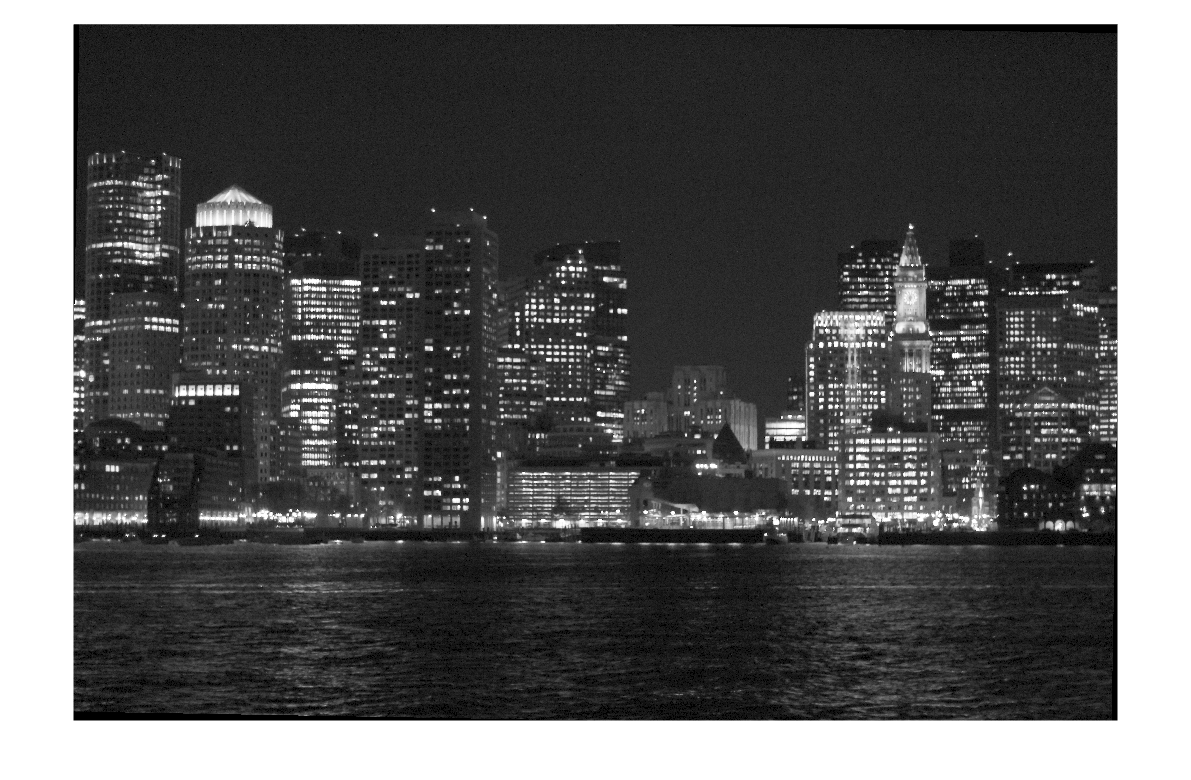

imgRotated = imrotate(imgGamma, -1, "crop");
imshow(imgRotated)

imgAdjusted = im2uint8(imgRotated);
imwrite(imgAdjusted, "Final Boston Bridge.JPG");

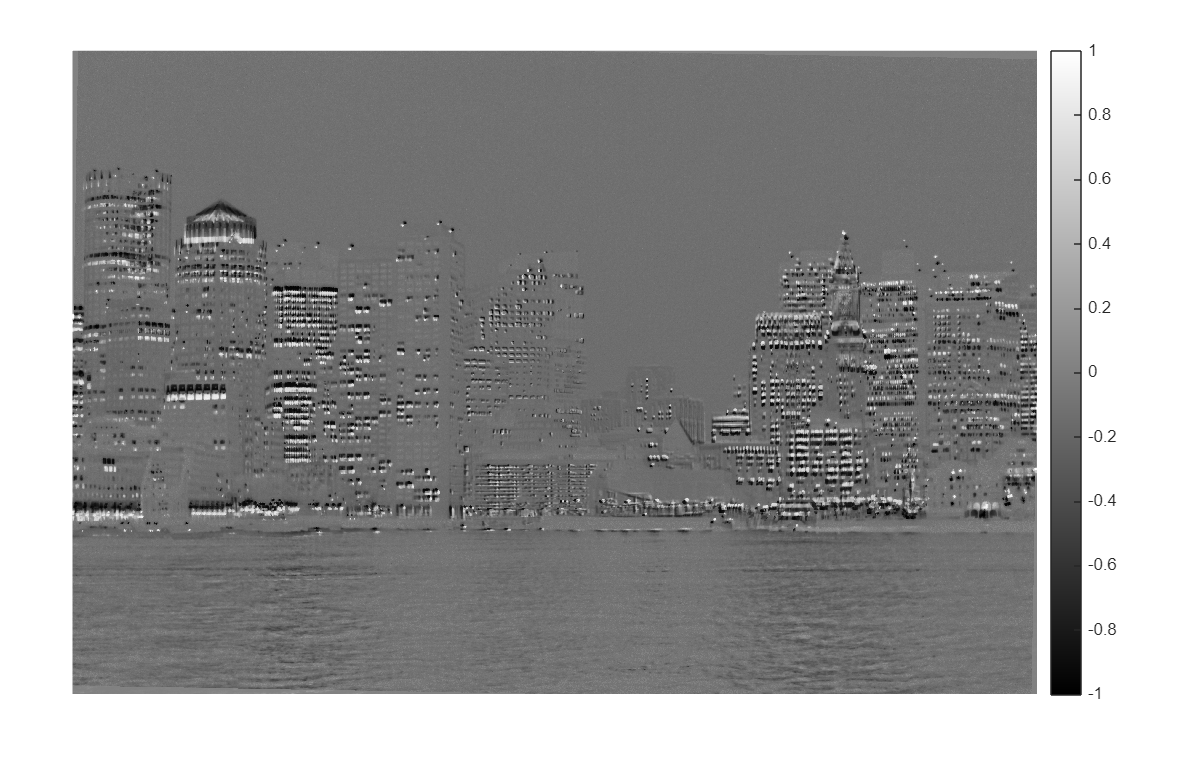

imgDiff = im2double(imgGray) - im2double(imgAdjusted);
imshow(imgDiff, [])
colorbar